%% 1. Obliczenie współczynników licznika i mianownika
% G(s) = (b2*s^2 + b1*s + b0) / (a4*s^4 + a3*s^3 + a2*s^2 + a1*s + a0)

% Mianownik (a)
a4 = Det;
a3 = b_x * J_tot + b_theta * M_tot;
a2 = b_x * b_theta - M_tot * m * g * l;
a1 = -b_x * m * g * l;
a0 = 0;

% Licznik (b)
b2 = -(M_tot + m*l/R);
b1 = -b_x;
b0 = 0; 

%% 2. Utworzenie Transmitancji Ciągłej G(s)
num = [b2, b1];          % Współczynniki przy s^2, s^1, s^0
den = [a4, a3, a2, a1];  % Współczynniki przy s^4, s^3, s^2, s^1, s^0

G_s = tf(num, den);

% Uproszczenie transmitancji (Redukcja rzędu)
% Ponieważ a0=0 i b0=0, w liczniku i mianowniku jest "wolne s".
% Funkcja minreal skróci je, redukując rząd z 4 do 3 (co jest poprawne fizycznie).
% G_s = minreal(G_s_raw);

disp('Obliczona Transmitancja Ciągła G(s):');

Obliczona Transmitancja Ciągła G(s):


printsys(num, den, 's'); % Wyświetlenie w ładnej formie w konsoli

 
num/den = 
 
                     -5.5 s - 0.1
   -----------------------------------------------
   0.034375 s^3 + 0.17825 s^2 - 2.5651 s - 0.14715


% Alternatywnie po prostu:
% G_s

%% 3. Odpowiedź skokowa (Symulacja)
% Uwaga: Układ jest niestabilny, więc symulujemy krótki czas,
% aby wykres nie uciekł do nieskończoności.

t_sim = 0:0.01:1.5; % Czas symulacji: 1.5 sekundy
[y_cont, t_cont] = step(G_s, t_sim);

% Skalowanie dla małego skoku (funkcja step domyślnie robi skok o 1)
% Jeśli chcesz zobaczyć skok o 0.1 (jak w Simulinku), pomnóż wynik:
u_step_val = 0.1;
y_cont = y_cont * u_step_val;

%% 4. Rysowanie wykresu
% figure;
% plot(t_cont, y_cont, 'b', 'LineWidth', 2);
% grid on;
% title(['Odpowiedź skokowa transmitancji ciągłej (u=', num2str(u_step_val), ')']);
% xlabel('Czas [s]');
% ylabel('Kąt \theta [rad]');
% legend('Model G(s)');

% Sprawdzenie biegunów (Potwierdzenie niestabilności)
disp('Bieguny układu (Poles):');

Bieguny układu (Poles):


disp(pole(G_s)); 

  -11.5913
    6.4630
   -0.0571



% Jeśli jeden biegun jest dodatni -> układ niestabilny.

%% 7. Przygotowanie do dyskretyzacji (Bonus dla Ciebie)
% Aby przejść na dyskretne równanie różnicowe dla PID, użyj c2d.
Ts = 0.01; % Przykładowy czas próbkowania 10ms (100Hz)
G_z = c2d(G_s, Ts, 'zoh');

disp('Transmitancja Dyskretna G(z):');

Transmitancja Dyskretna G(z):


G_z

G_z =
 
  -0.007869 z^2 + 0.0001329 z + 0.007733
  --------------------------------------
    z^3 - 2.957 z^2 + 2.906 z - 0.9495
 
Sample time: 0.01 seconds
Discrete-time transfer function.



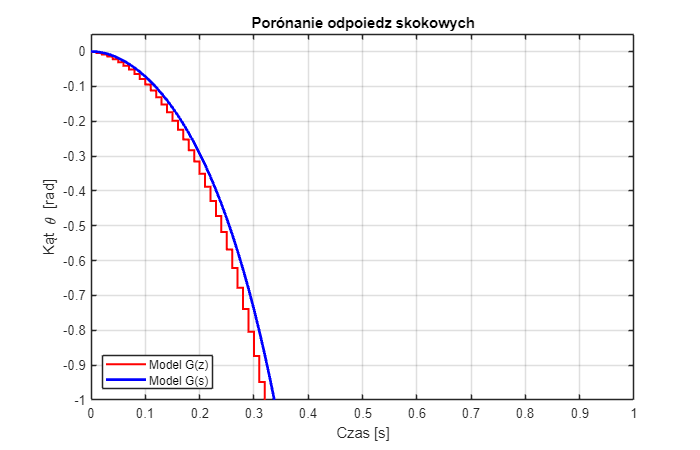


% Współczynnik W (przy z^3 w mianowniku)
W = a4 + a3*Ts + a2*Ts^2 + a1*Ts^3;

% Współczynniki P (dla mianownika)
% Mianownik w LaTeX: W*z^3 - P1*z^2 - P2*z - P3
% Pamiętajmy o znakach przy potęgach z.
% Po rozwinięciu (1-z^-1)^3 wychodzi: 1 - 3z^-1 + 3z^-2 - z^-3
% Więc współczynniki wielomianu mianownika to:

den_euler_3 = W;                              % przy z^3
den_euler_2 = -(3*a4 + 2*a3*Ts + a2*Ts^2);    % przy z^2
den_euler_1 = (3*a4 + a3*Ts);                 % przy z^1
den_euler_0 = -a4;                            % przy z^0

% Współczynniki Q (dla licznika)
% Licznik w LaTeX: Q0*z^3 + Q1*z^2
% Wynikają z b2*Ts^2*(z-1)*z^2 + b1*Ts^3*z^3 (po sprowadzeniu do wsp. mian)

num_euler_3 = b2*Ts^2 + b1*Ts^3;              % przy z^3 (Twoje Q0)
num_euler_2 = -b2*Ts^2;                       % przy z^2 (Twoje Q1)
num_euler_1 = 0;
num_euler_0 = 0;

% Składamy transmitancję Eulera
num_E = [num_euler_3, num_euler_2, num_euler_1, num_euler_0];
den_E = [den_euler_3, den_euler_2, den_euler_1, den_euler_0];

G_euler = tf(num_E, den_E, Ts);

t_sim = 0:Ts:1.5; 
[y_disc, t_disc] = step(G_z, t_sim);
[y_euler, t_euler] = step(G_euler, t_sim);
u_val = 0.1;
y_disc = y_disc * u_val;
y_euler = y_euler * u_val;

figure('Position', [100, 100, 700, 450]);
stairs(t_euler, y_euler, 'r-', 'LineWidth', 1.5); hold on;
plot(t_cont, y_cont, 'b', 'LineWidth', 2);
grid on;

xlim([0, 1]);
ylim([-1, 0.05]); 

% Opisy
xlabel('Czas [s]');
ylabel('Kąt \theta [rad]');
title('Porónanie odpoiedz skokowych');
legend('Model G(z)', 'Model G(s)', 'Location', 'southwest');